load('proj2Data')

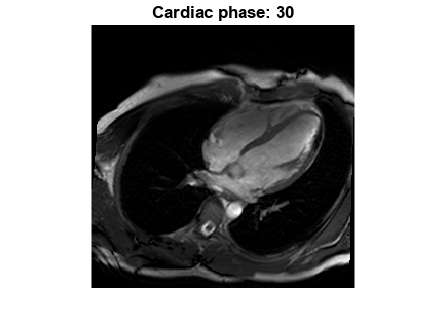

figure
nFrames = 30;
for index = 1:nFrames
    imagesc(squeeze(image_3d(:, :, index)))
    % Set the intensity scale based on the first image:
    if (index == 1)
        cLim_v = get(gca, 'CLim');
    else
        set(gca, 'CLim', cLim_v)
    end
    axis image
    axis off
    colormap(gray)
    title(['Cardiac phase: ', num2str(index)])
    drawnow
    mov(index) = getframe;
end

fps = 8;          % frames per second.
nReps = 4;    % number of repetitions.
movie(mov, nReps, fps)

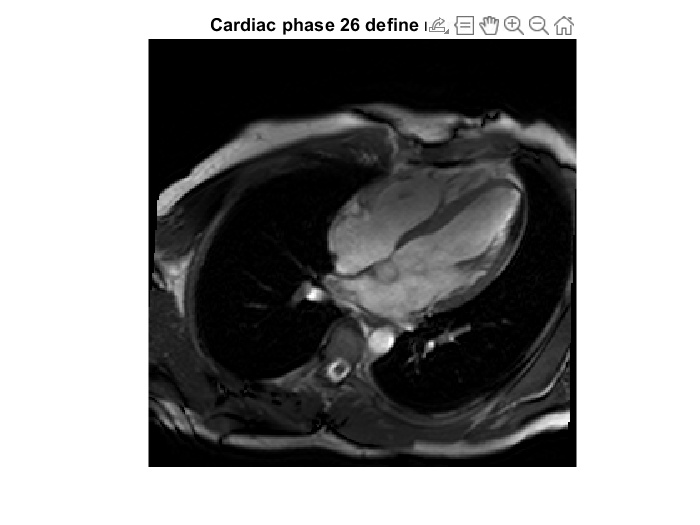

% Define the major and minor axes of the ellipse in each frame:
skip = 5;   % Number of phases to skip.
nVols = length(1:skip:nFrames);
volume_v = zeros(1, nVols);
for index = 1:skip:nFrames
    imagesc(squeeze(image_3d(:, :, index)))
    set(gca, 'CLim', cLim_v)
    axis image
    axis off
    colormap(gray)
    % Get axes:    
    title(['Cardiac phase ', num2str(index), ' define major axis'])
    % Insert your code here to measure the major axis:
    a_xy = ginput(2);
    a = pdist(a_xy);
    title(['Cardiac phase ', num2str(index), ' define minor axis'])
    % Insert your code here to measure the minor axis:
    b_xy = ginput(2);
    b = pdist(b_xy);
    volIndex = (index-1)/skip + 1;
    % Enter your code here to calculate the LV volume:
    volume_v(volIndex) = ((dx)^3 ) * 4*pi*a*(b^2)/24; 
end

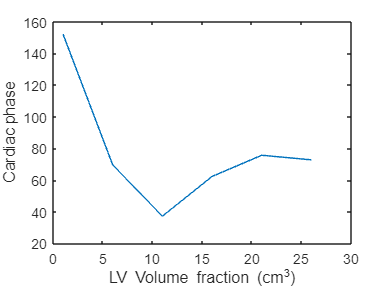

plot(1:skip:nFrames, volume_v)
xlabel('LV Volume fraction (cm^3)') 
ylabel('Cardiac phase') 

max(volume_v)

ans = 152.0259

min(volume_v)

ans = 37.1790